# Face Recognition Project by 2G8

This is the live editor script for this project. In this script, I present all the steps that we use to train the model to detect faces. If you want to test the model. You can skip to step 5.

## 1) Data Collection

In data collecetion, we are using 2 method:

- Using a script in matlab to capture our face with webcam

- Take the picture ourselve usiing phone/camera

You can run this script to capture the face using webcam:

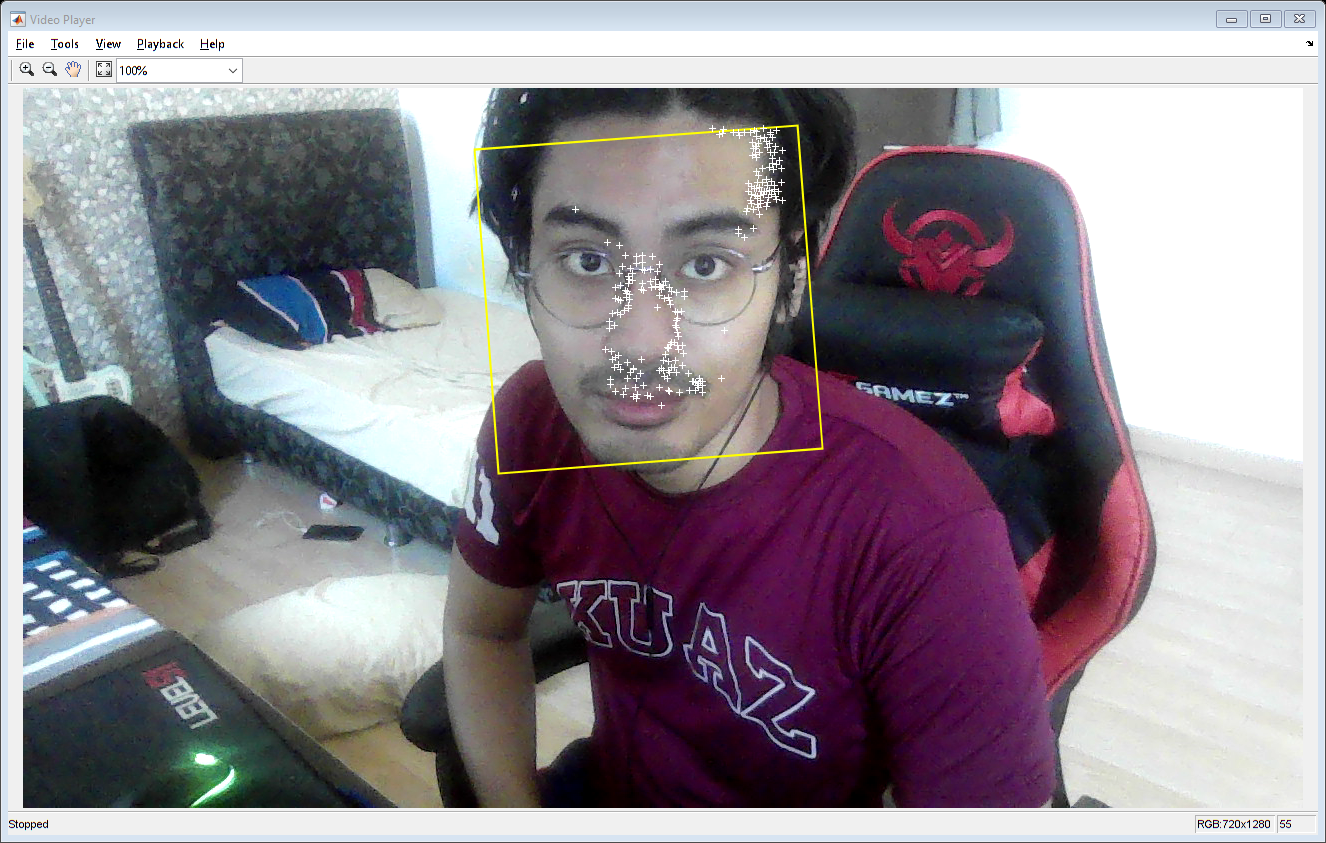

% Create the face detector object.
faceDetector = vision.CascadeObjectDetector('FrontalFaceCART','MinSize',[150,150]);

% Here the loop runs for 300 times you can change the threshold (n) based on the number of training data you need
n = 55;

% change str to s01,s02,s03,.... for saving  upto how many subjects you want to save for saving in respective folders for 
% imwrite in line 88

str = 's01';

% Create the point tracker object.
pointTracker = vision.PointTracker('MaxBidirectionalError', 2);

% Create the webcam object.
cam = webcam();

% Capture one frame to get its size.
videoFrame = snapshot(cam);
frameSize = size(videoFrame);

% Create the video player object.
videoPlayer = vision.VideoPlayer('Position', [100 100 [frameSize(2), frameSize(1)]+30]);
runLoop = true;
numPts = 0;
frameCount = 0;
i=1;

while runLoop && frameCount < n

    % Get the next frame.
    videoFrame = snapshot(cam);
    videoFrameGray = rgb2gray(videoFrame);
    frameCount = frameCount + 1;

    if numPts < 10
        % Detection mode.
        bbox = faceDetector.step(videoFrameGray);

        if ~isempty(bbox)
            % Find corner points inside the detected region.
            points = detectMinEigenFeatures(videoFrameGray, 'ROI', bbox(1, :));

            % Re-initialize the point tracker.
            xyPoints = points.Location;
            numPts = size(xyPoints,1);
            release(pointTracker);
            initialize(pointTracker, xyPoints, videoFrameGray);

            % Save a copy of the points.
            oldPoints = xyPoints;

            % Convert the rectangle represented as [x, y, w, h] into an
            % M-by-2 matrix of [x,y] coordinates of the four corners. This
            % is needed to be able to transform the bounding box to display
            % the orientation of the face.
            bboxPoints = bbox2points(bbox(1, :));

            % Convert the box corners into the [x1 y1 x2 y2 x3 y3 x4 y4]
            % format required by insertShape.
            bboxPolygon = reshape(bboxPoints', 1, []);

            % Display a bounding box around the detected face.
            videoFrame = insertShape(videoFrame, 'Polygon', bboxPolygon, 'LineWidth', 3);

            % Display detected corners.
            videoFrame = insertMarker(videoFrame, xyPoints, '+', 'Color', 'white');
        end

    else
        % Tracking mode.
        [xyPoints, isFound] = step(pointTracker, videoFrameGray);
        visiblePoints = xyPoints(isFound, :);
        oldInliers = oldPoints(isFound, :);

        numPts = size(visiblePoints, 1);

        if numPts >= 10
            % Estimate the geometric transformation between the old points
            % and the new points.
            [xform, oldInliers, visiblePoints] = estimateGeometricTransform(...
                oldInliers, visiblePoints, 'similarity', 'MaxDistance', 4);

            % Apply the transformation to the bounding box.
            bboxPoints = transformPointsForward(xform, bboxPoints);

            % Convert the box corners into the [x1 y1 x2 y2 x3 y3 x4 y4]
            % format required by insertShape.
            bboxPolygon = reshape(bboxPoints', 1, []);
            imwrite(videoFrame,[ 'photos\',str,'\',int2str(i), '.jpg']);
            % Display a bounding box around the face being tracked.
            videoFrame = insertShape(videoFrame, 'Polygon', bboxPolygon, 'LineWidth', 3);

            % Display tracked points.
            videoFrame = insertMarker(videoFrame, visiblePoints, '+', 'Color', 'white');
            
            % Reset the points.
            oldPoints = visiblePoints;
            setPoints(pointTracker, oldPoints);
            i = i+1;
        end

    end

    % Display the annotated video frame using the video player object.
    step(videoPlayer, videoFrame);

    % Check whether the video player window has been closed.
    runLoop = isOpen(videoPlayer);
end
% Clean up.
clear cam;
release(videoPlayer);

release(pointTracker);
release(faceDetector);




## 2) Date Pre-Processing

In this step, we are going to process the data before we are ready for training model step.

The steps to process the data:

- Detect the face using CascadeObjectDetector from Vision package.

- Crop the picture according the bounding box we receive from step 1.

- Save the cropped images into the label folder.

% This Program will detect face and crop the face and save in croppedfolder.
% looping through all subjects and cropping faces if found
% extract the subject photo and crop faces and saving it in to respective
% folders
n=5;
for i =1:n
   str = ['s0',int2str(i)];
  ds1 = imageDatastore(['photos\',str],'IncludeSubfolders',true,'LabelSource','foldernames');
   cropandsave(ds1,str);
end

Error using imageDatastore (line 137)
Folder 'photos\s01' does not have any files or is empty.

Resize the picture to match the input layer of the model

 im = imageDatastore('croppedfaces','IncludeSubfolders',true,'LabelSource','foldernames');
 % Resize the images to the input size of the net
 im.ReadFcn = @(loc)imresize(imread(loc),[224,224]);

Split the data into train and test set.

 [Train ,Test] = splitEachLabel(im,0.8,'randomized');


## 3) Train the model

In this step, we are going to train the model.

The steps:

-  Load the model

-  Replace the classification layer with the desired number of class output.

-  Replace the learnable layer with a new learnable layer that match with our number of class.

- Setting the model options

- Train the model

- Save the model

% n is the number of subjects
n = 5;
% You can press stop button manually on tranining plot(on top right corner besides number of iterations) once accuracy reaches upto desired level

Load the Model

 net = googlenet;
 
 inputSize = net.Layers(1).InputSize;
 
 if isa(net,'SeriesNetwork') 
  lgraph = layerGraph(net.Layers); 
 else
  lgraph = layerGraph(net);
 end
 

Replace the layers

 [learnableLayer,classLayer] = findLayersToReplace(lgraph);

numClasses = n;

if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
end

lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

Setting up the options for the training

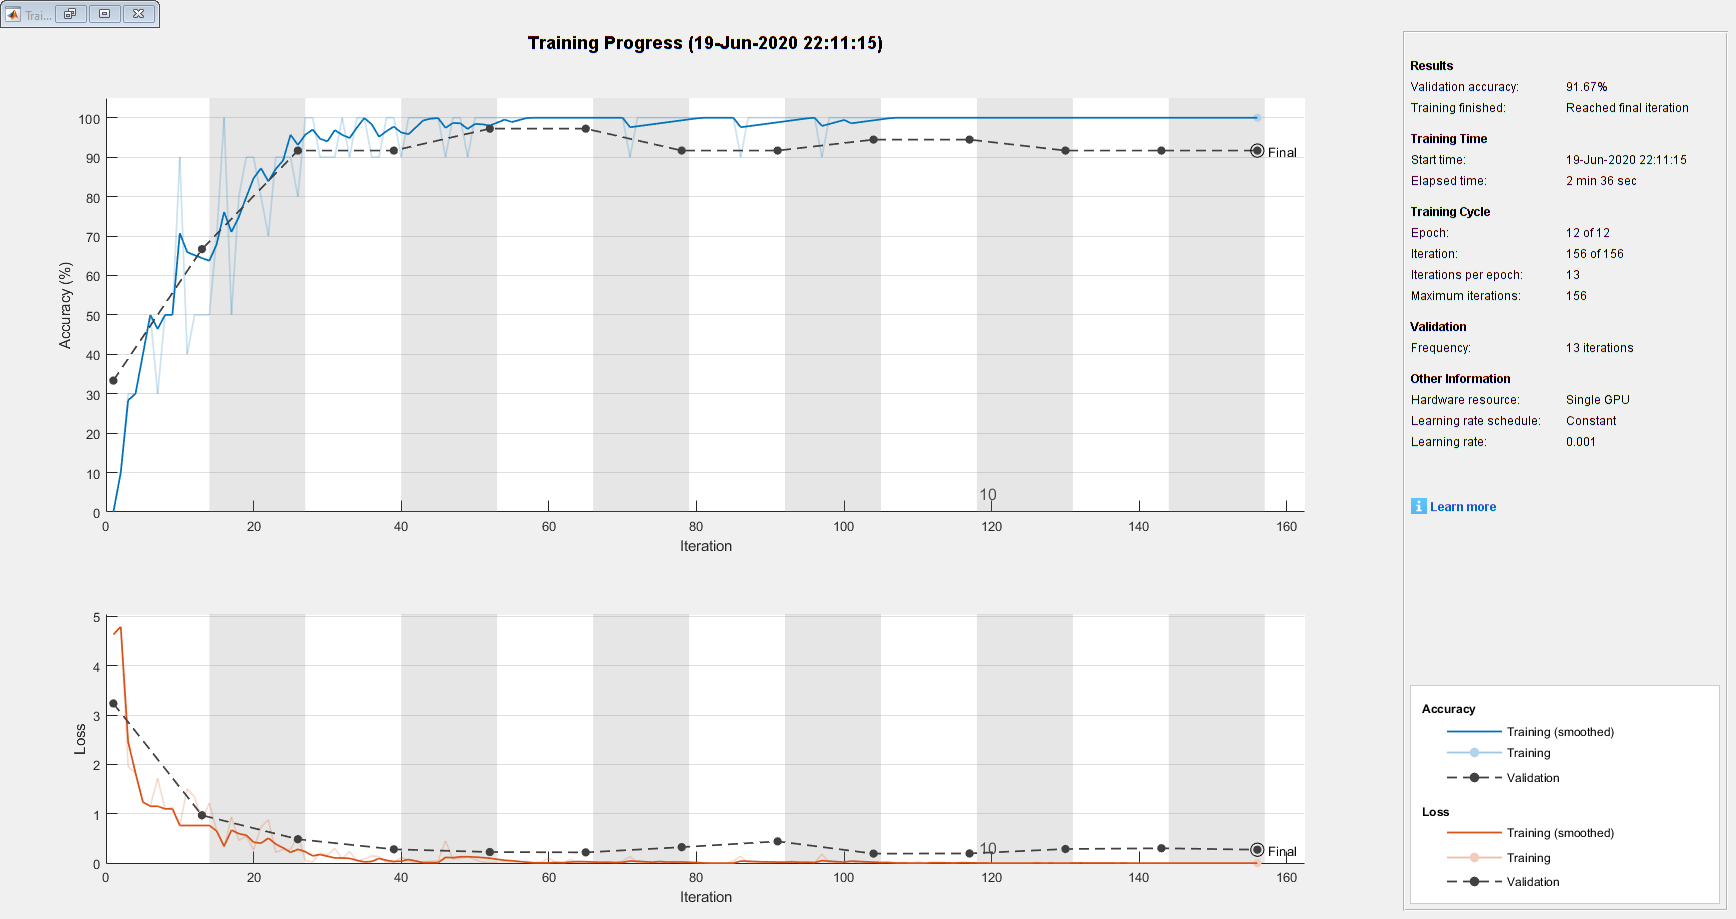

layers = lgraph.Layers;
connections = lgraph.Connections;

layers(1:10) = freezeWeights(layers(1:10));
lgraph = createLgraphUsingConnections(layers,connections);

augimdsTrain = augmentedImageDatastore(inputSize(1:2),Train);
augimdsTest = augmentedImageDatastore(inputSize(1:2),Test);

miniBatchSize = 10;
valFrequency = floor(numel(augimdsTrain.Files)/miniBatchSize);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',12, ...
    'InitialLearnRate',1e-3, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsTest, ...
    'ValidationFrequency',valFrequency, ...
    'Verbose',false, ...
    'Plots','training-progress');
net = trainNetwork(augimdsTrain,lgraph,options);

Train the Model

[YPred,probs] = classify(net,augimdsTest);

Save the Model

 model_google_1 = net;
 save model_google_1

## 4) Evaluate the model

names = Test.Labels;
pred = (YPred==names);
s = size(pred);
acc = sum(pred)/s(1);
fprintf('The accuracy of the test set is %f %% \n',acc*100);

The accuracy of the test set is 91.666667 % 



c = confusionmat(YPred,names)

c =      7     0     0     1     1
     0     6     0     0     0
     0     1     7     0     0
     0     0     0     7     0
     0     0     0     0     6


display('This is the confusion matrix');

This is the confusion matrix


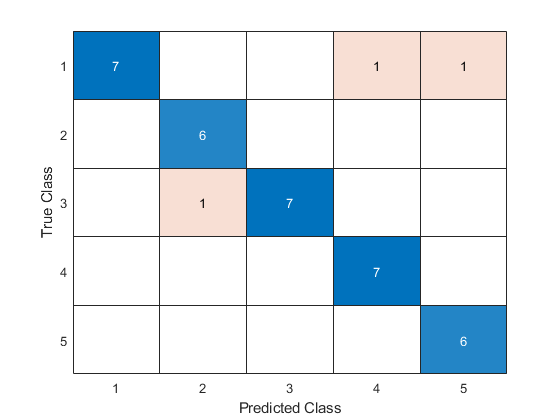

confusionchart(c)

## 5) Make Predictions

load model_google_1.mat;

net = model_google_1 ;

img = imread('.\Image_to_test\test_zarif.jpg');
 [img,face] = cropface(img);
% face value is 1 when it detects face in image or 0
 if face == 1
   img = imresize(img,[224 224]);
   [predict,scores] = classify(net,img);
 end

% nameofs03 = 'name of subject 3';
if predict=='s01'
   name='Aliff'; 
   disp(name)
   disp(scores)
elseif  predict=='s02'
   name='Amin';
   disp(name)
   disp(scores)
elseif  predict=='s03'
   name='Aqiff';
   disp(name)
   disp(scores)
elseif  predict=='s04'
   name='Akif';
   disp(name)
   disp(scores)
elseif  predict=='s05'
   name='Zarif';
   disp(name)
   disp(scores)
else
    disp("Nothing detected")
end

Zarif


    0.0039    0.0024    0.0049    0.0146    0.9742



cropandsave code:

function  cropandsave(im,str)
    % This function is used to save the cropped image into croppedfaces
    % folder.
    j = 1;
    T = countEachLabel(im);
    n = T(1,2).Variables;
    for i = 1:n
        i1 = readimage(im,i);
        [img,face] = cropface(i1);
        if face==1
            imwrite(img,['croppedfaces\', str,'\',int2str(j), '.jpg']);
            j = j+1;
        end
    end
end

cropface code:

function [J,face] = cropface(img)
    % This function is used to detect a face in an image and cropped
    % according to bounding box of the face.
    FaceDetect = vision.CascadeObjectDetector('FrontalFaceCART','MinSize',[150,150]);
    bbox=step(FaceDetect,img);
    if ~isempty(bbox)
        for i=1:size(bbox,1)
        J=imcrop(img,bbox(i,:));
        end
        face = 1;
    else
        img = imrotate(img,-90);
        bbox=step(FaceDetect,img);
        if ~isempty(bbox)
            for i=1:size(bbox,1)
            J=imcrop(img,bbox(i,:));
            end
        face = 1;
        else
        J = img;
        face = 0;
        end
    end
end